## Setup

close all; 
% clear 

xTorso = 0.12; % x distance from body to foot 
g = 9.807; 
Ts = 0.005; %sample time (s)
zRobot = 0.78;
zModel = 0.68; 
swingHeight = 0.1; 

### Create the Linear Inverted Pendulum Model

Create a discrete state-space model of the linear inverted pendulum.

w = sqrt(g/zModel); 
A = [0   1 0    0
    g/zModel 0 0    0
    0    0 0    1
    0    0 g/zModel 0]; 
B = [0 0
     1 0
     0 0
     0 1]; 
C = [1 0 0 0
     0 0 1 0]; 
D = [0 0;0 0]; 

lipm = ss(A,B,C,D); 
lipmD = c2d(lipm, Ts); 

Ad = lipmD.A; 
Bd = lipmD.B;
Cd = lipmD.C;
Dd = lipmD.D;

x0  = -0.12; %-0.18; 
dx0 = 0.4; %0.48; 
y0  = 0; %-0.35; 
dy0 = 0; %1.48; 
state0 = [x0 dx0 y0 dy0]'; 
robotpos0 = [0; 0; zModel]; %[x0; y0; zModel]; 

### Pick Foot Placements 

footpos = [0.12 0   0;
          -0.12 0.1 0;
           0.12 0.2 0;
          -0.12 0.3 0;
           0.12 0.3 0]; 

xc = 0; 
yc = 0; 
dxc = dx0; 
dyc = dy0; 
cpointx = xc + dxc/w; 
cpointy = yc + dyc/w; 
    
cpdesired = [-0.24 0.1];
steptimedes = 0.5; 
px = findZMP(w, steptimedes, cpdesired(1), cpointx); 
py = findZMP(w, steptimedes, cpdesired(2), cpointy); 

fhold_x0 = px; %0; 
fhold_y0 = py; %0; 

### Initialize Graphics

Graphics objects help us animate the model. 

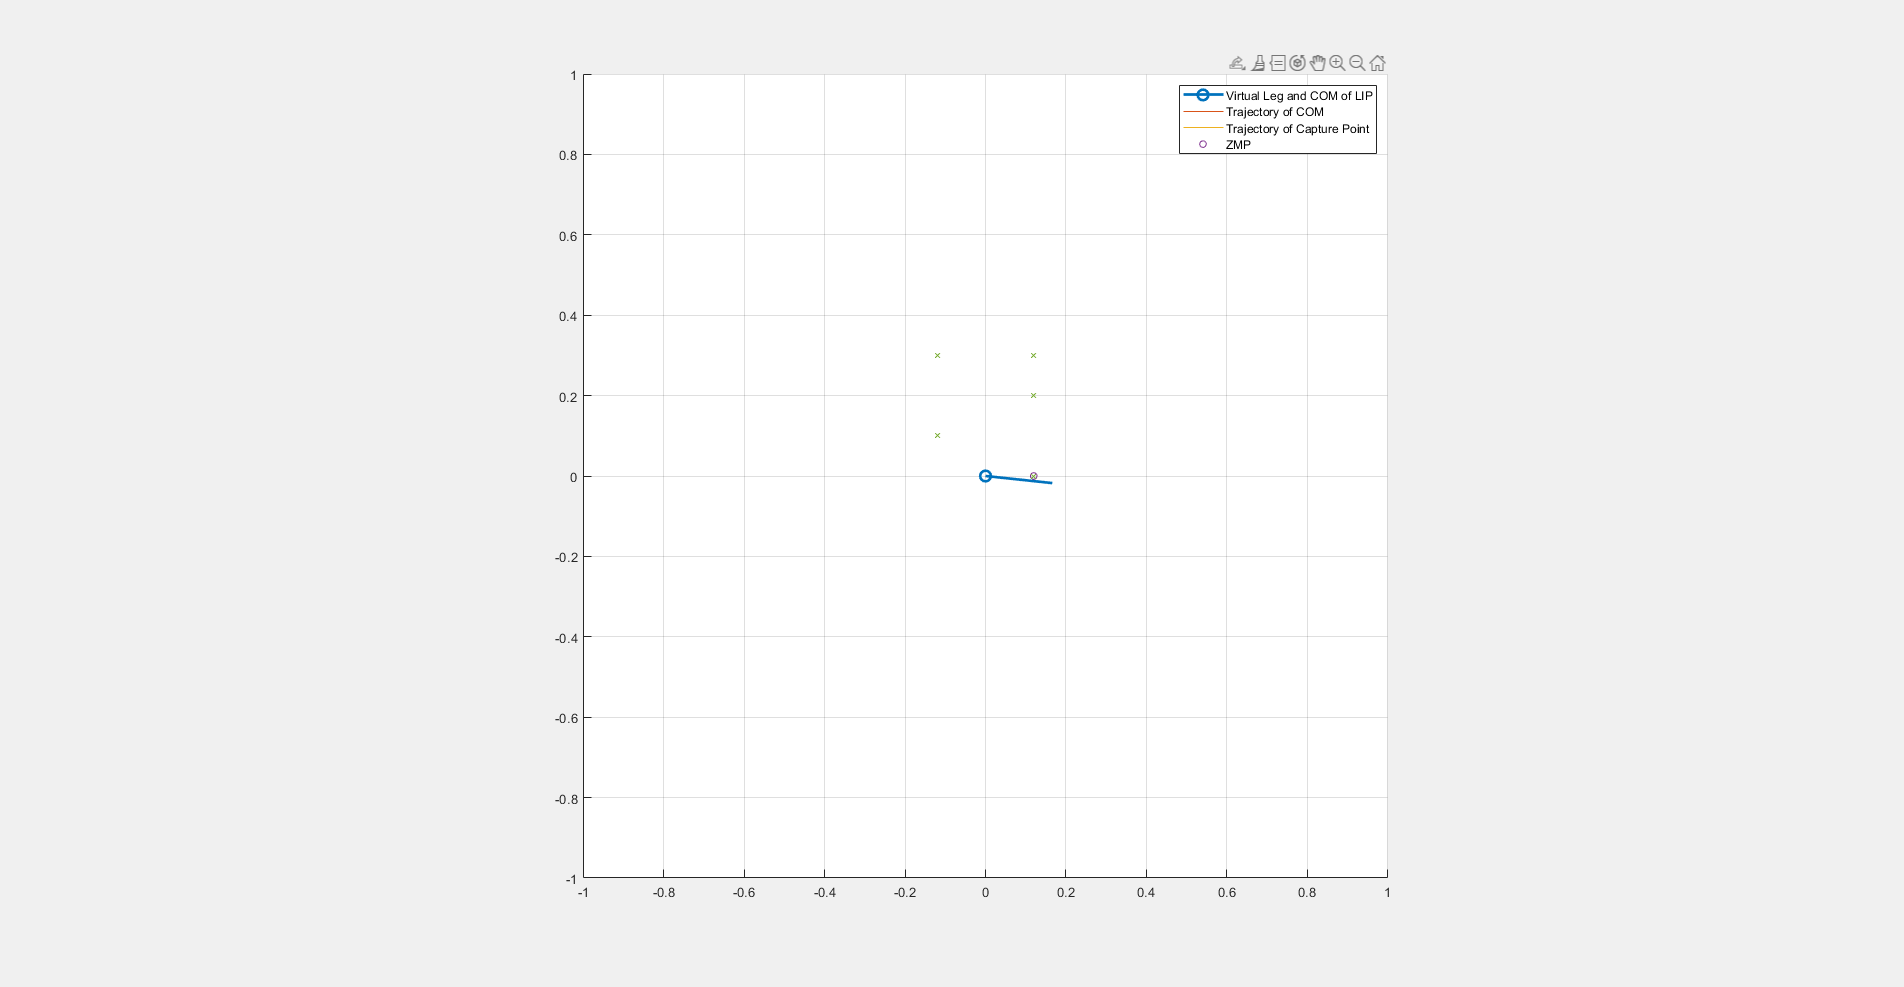

hFig = figure; 
hFig.Visible = 'on'; % for livescript 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
hAx  = axes(hFig); 

% create handles for plots 
hold(hAx, 'on'); 
hLeg  = plot3(hAx,[fhold_x0,robotpos0(1)],[fhold_y0,robotpos0(2)],[0,robotpos0(3)],...
                '-o','MarkerIndices',2,'LineWidth',2,'MarkerSize',8); % represents com + leg 
hCom = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents com traj
hCap = plot3(hAx,robotpos0(1),robotpos0(2),robotpos0(3)); % represents capture point traj 
hZMP = plot3(hAx,0.12,0,0,'o','MarkerSize',5); % represents ZMPs
hFoot = plot3(hAx,footpos(:,1),footpos(:,2),footpos(:,3),'x','MarkerSize',5); 
hold(hAx, 'off'); 

grid(hAx, 'on'); 
view(hAx,2)
axis equal 
hAx.XLim = [-1 1]; %[-3*zRobot 3*zRobot];
hAx.YLim = [-1 1]; %[-3*zRobot 3*zRobot]; 
legend(hAx, 'Virtual Leg and COM of LIP','Trajectory of COM','Trajectory of Capture Point',...
    'ZMP','Location', 'northeast');   

### Get desired foot positions 

% hFig.WindowButtonUpFcn = {@getFootPos}; %'disp(hAx.CurrentPoint(1,1:2));'; 


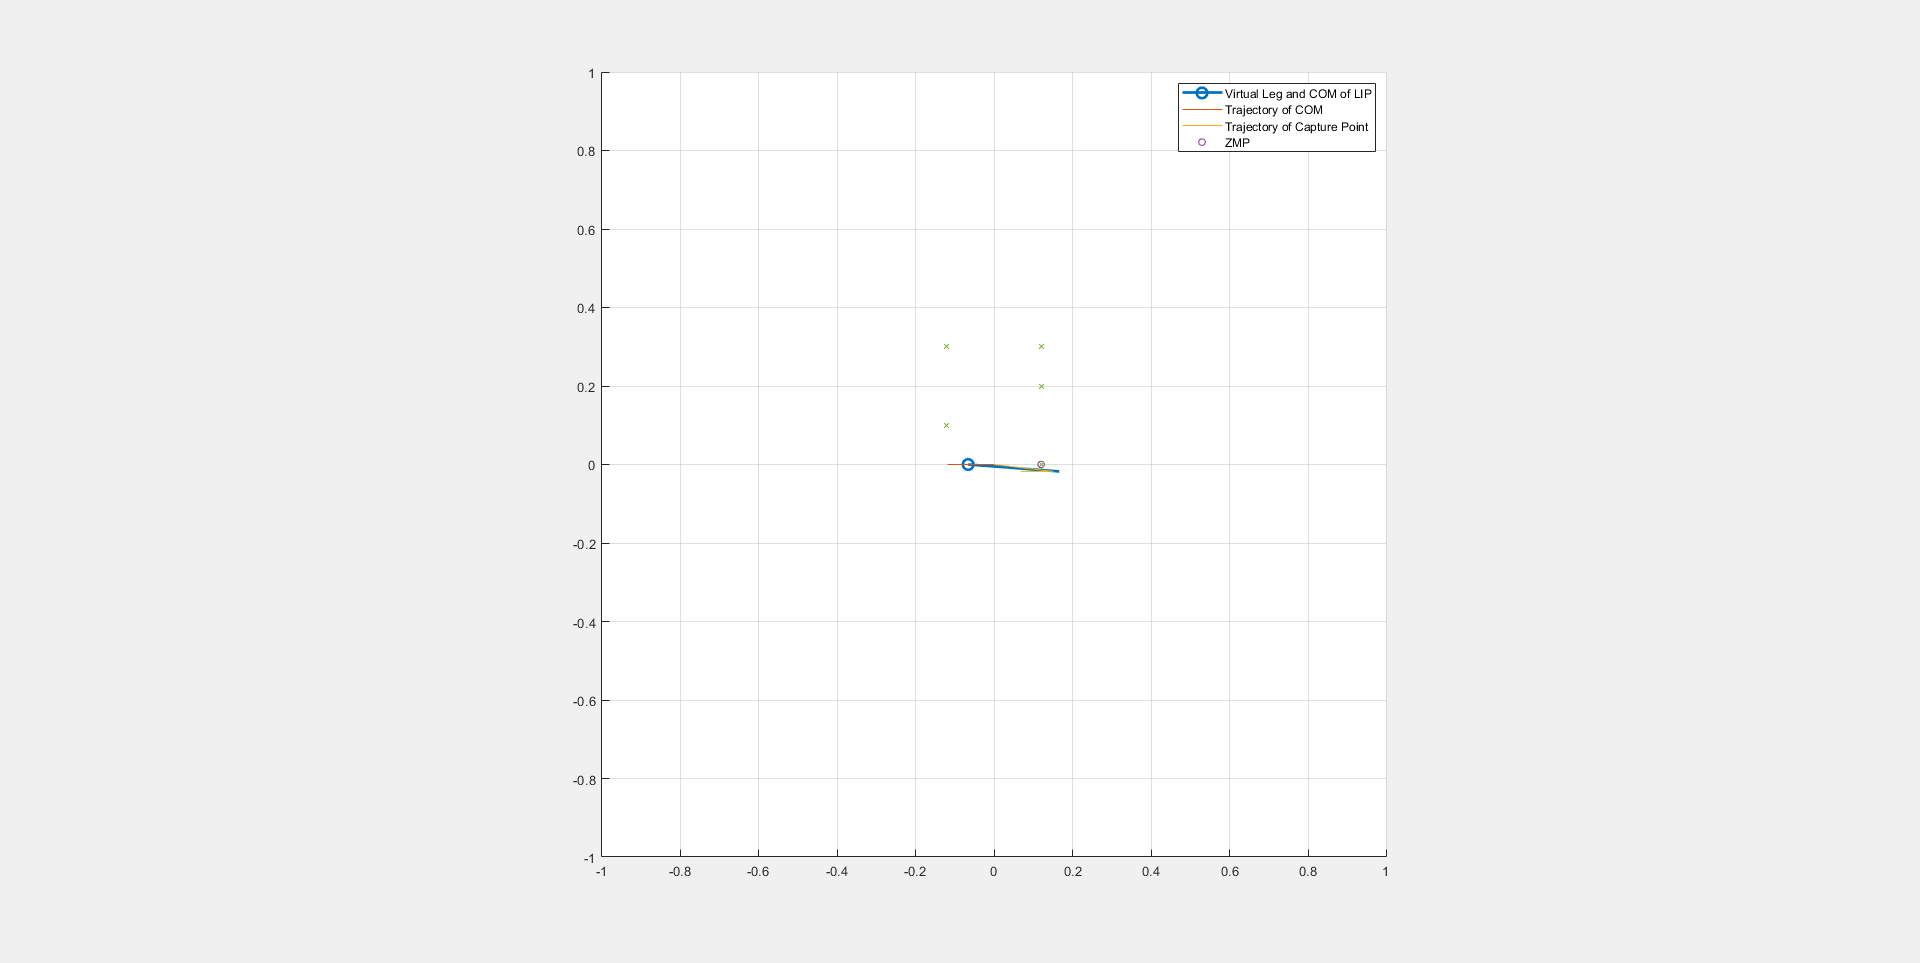


u0 = [0 0]'; 
% fhold_x0 = px; %0; 
% fhold_y0 = py; %0; 
% state0 = [state0(1)-fhold_x0; 
%           state0(2); 
%           state0(3)-fhold_y0;
%           state0(4)]; 
      
for idx = 1:round(steptimedes/Ts)
    state1 = Ad*state0 + Bd*u0; 
    meas1  = Cd*state1 + Dd*u0; 
    state0 = state1; 
    
    xc = meas1(1); 
    yc = meas1(2);
    dxc = state1(2); 
    dyc = state1(4); 
    cpointx = xc + dxc/w; 
    cpointy = yc + dyc/w; 
    
    cappos = [fhold_x0 + cpointx; 
              fhold_y0 + cpointy; 
              zModel]; 
    bodypos = [xc; %fhold_x0 + xc;
               yc; %fhold_y0 + yc;
               zModel]; 
    points = [fhold_x0, bodypos(1);
              fhold_y0, bodypos(2);
              0,        bodypos(3)]; 
    % update graphics 
    updateLine(hLeg, points);
    appendLine(hCom, bodypos); 
    appendLine(hCap, cappos); 
    pause(0.005); 
end 

### Change Foot

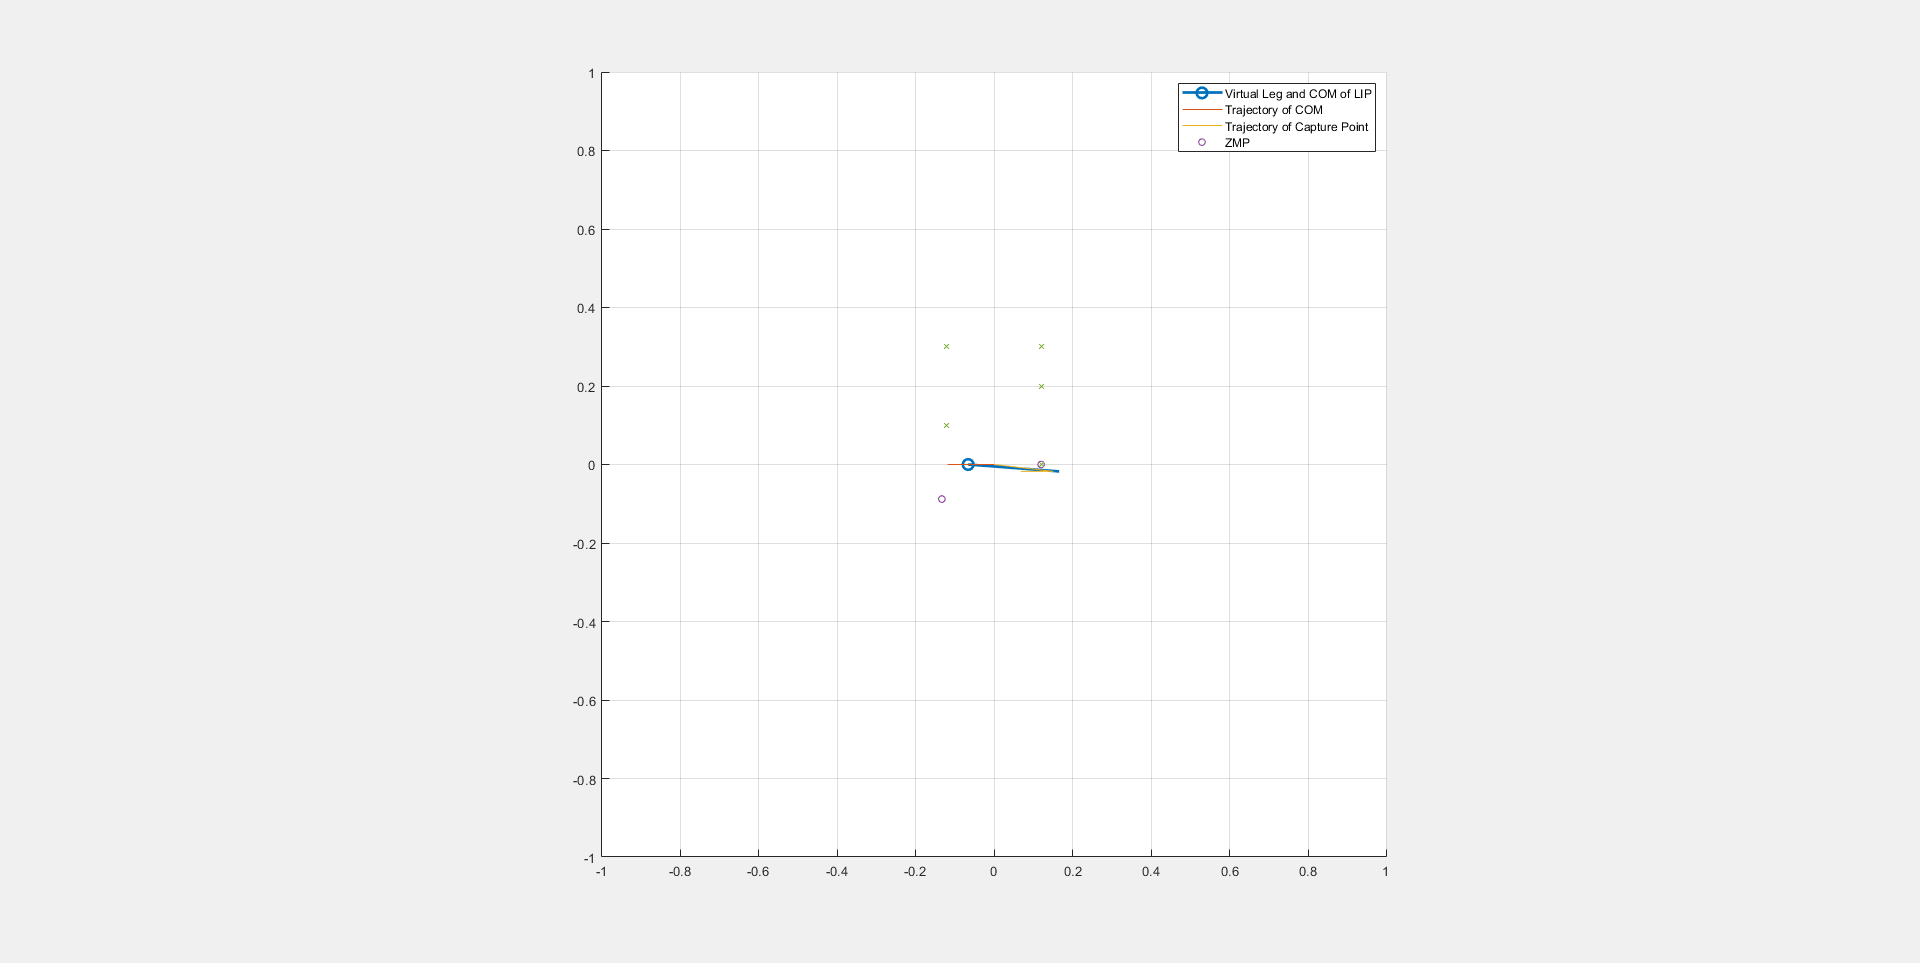

cpdesired = [0.1 0.5];
steptimedes = 0.5; 
px = findZMP(w, steptimedes, cpdesired(1), cpointx); 
py = findZMP(w, steptimedes, cpdesired(2), cpointy); 
fhold_x0 = px;  
fhold_y0 = py;
appendLine(hZMP, [fhold_x0, fhold_y0, 0]);

state0 = [state1(1)-fhold_x0; 
          state1(2); 
          state1(3)-fhold_y0;
          state1(4)]; 

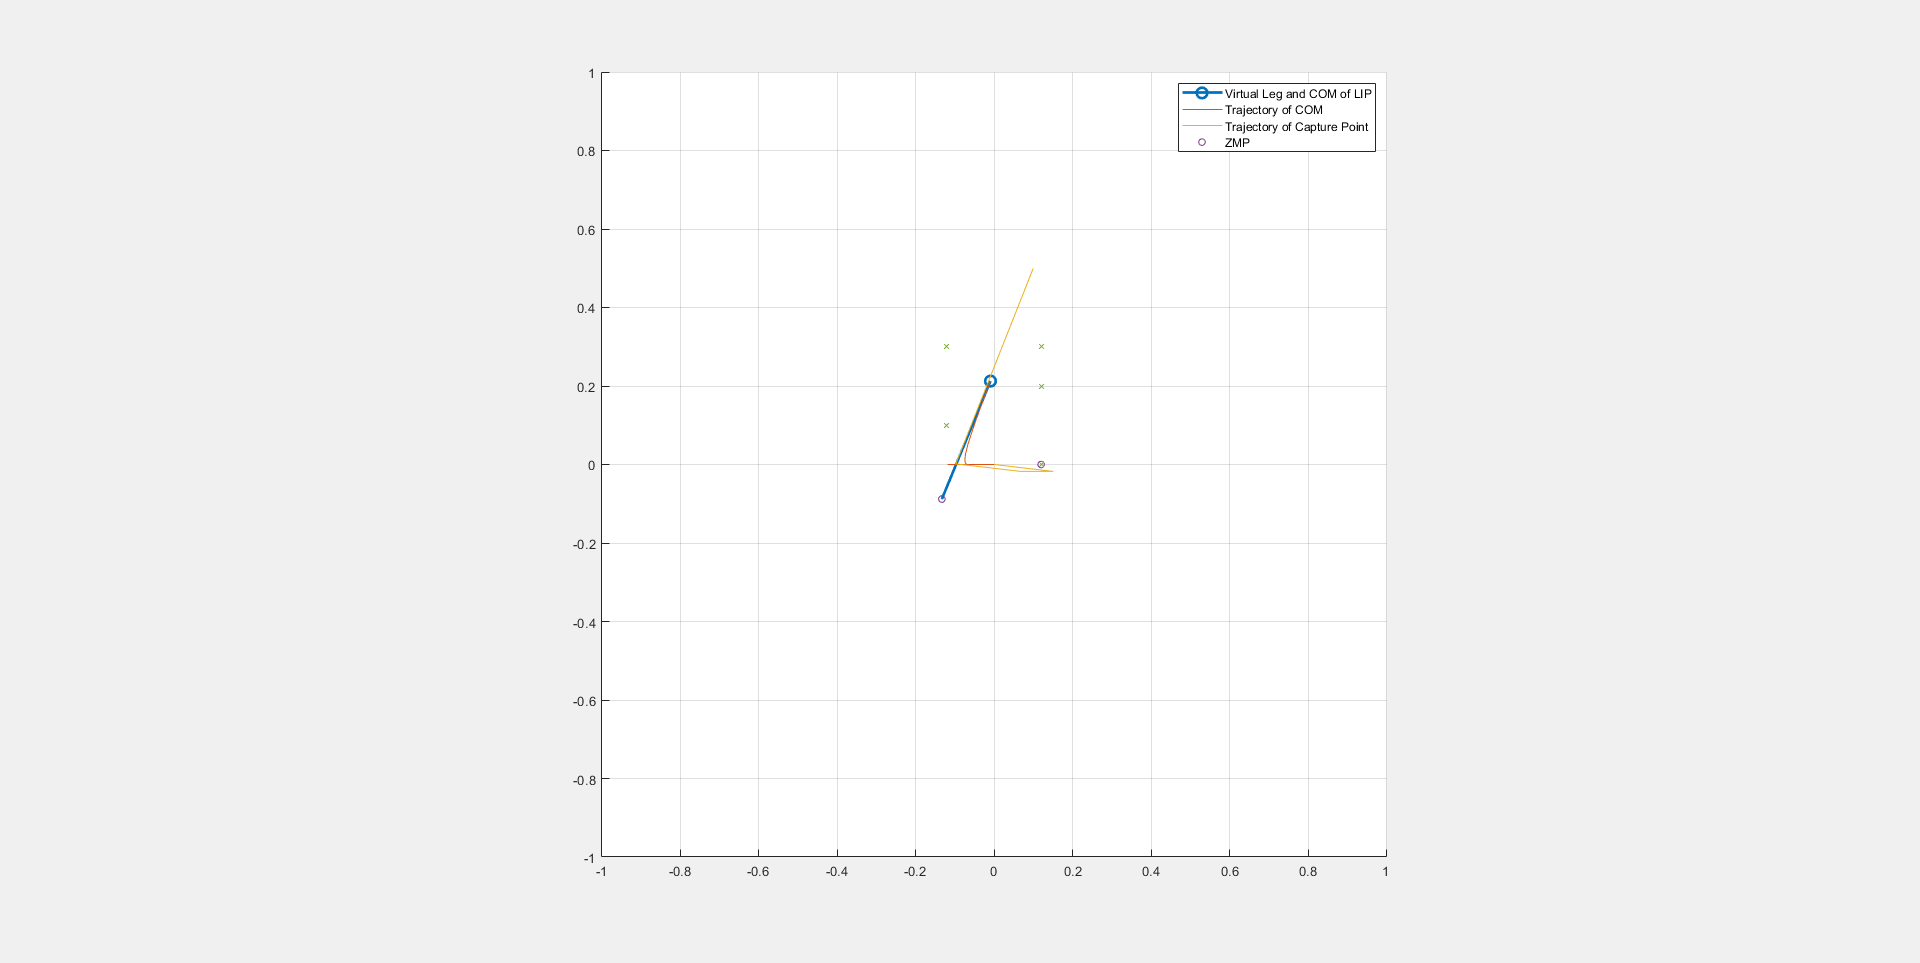


for idx = 1:100
    state1 = Ad*state0 + Bd*u0; 
    meas1  = Cd*state1 + Dd*u0; 
    state0 = state1; 
    
    xc = meas1(1); 
    yc = meas1(2);
    dxc = state1(2); 
    dyc = state1(4); 
    cpointx = xc + dxc/w; 
    cpointy = yc + dyc/w; 
    
    cappos = [fhold_x0 + cpointx; 
              fhold_y0 + cpointy; 
              zModel]; 
    bodypos = [fhold_x0 + xc;
               fhold_y0 + yc;
               zModel]; 
    points = [fhold_x0, bodypos(1);
              fhold_y0, bodypos(2);
              0,        bodypos(3)]; 
    % update graphics 
    updateLine(hLeg, points);
    appendLine(hCom, bodypos); 
    appendLine(hCap, cappos); 
    pause(0.005); 
end 

function px = findZMP(w, dT, cpdesired, cpcurrent)
    b = exp(w*dT); 
    px = 1/(1-b)*cpdesired - b/(1-b)*cpcurrent; 
end

function [states, timeVec, simStates] = stanceSim(fhold_x, fhold_y, state0, u0, modelVars, simStates)

    % Unpack variables
    Ts = modelVars.Ts;
    Ad = modelVars.Ad;
    Bd = modelVars.Bd;
    
    % Define time vector
    tInitial = simStates.timeVec(end) + modelVars.Ts; % don't let time overlap
    tFinal   = tInitial + modelVars.tSingleSupport; 
    timeVec  = tInitial:Ts:tFinal; 

    % Simulation loop
    nSteps = numel(timeVec); 
    states = zeros(size(state0,1),nSteps);  
    states(:,1) = state0; 
    for idx = 1:nSteps-1
        states(:,idx+1) = Ad*states(:,idx) + Bd*u0;
    end
    
    % Update the simStates structure
    simStates.timeVec = [simStates.timeVec timeVec(1:end-1)];
    newStates = [states(1,2:end)+fhold_x; states(3,2:end)+fhold_y; modelVars.zModel*ones([1 nSteps-1])];
    simStates.bodyPos = [simStates.bodyPos newStates];
end
    

Adds points to a graphics line object

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end

Callback for placing foot positions 

function getFootPos(imagefig,varargins)
    handleAxes = gca; 
    disp(handleAxes.CurrentPoint(1,1:2)); 
end 